## Radiator requirements and operating conditions

The radiator is used to cool the cooling liquid after leaving the cold plate back to its desired cooling temperature. The air is assumed to have ambient room temperature of a maximum of 20°C. A fan is used to create the airflow. The coolant inlet temperature is entering the radiator at 30°C, which is the maximum cold plate outlet temperature and should be cooled down to 25°C. 

#### Operating conditions

QDiss           = 2000;         % (W) Heat load
deltaTCoolant   = 5;            % (°C) Maximum temperature rise allowed
TCoolantOutMax  = 30;           % (°C) Maximum coolant outlet temperature = Raditor inlet temperature
TAmbient        = 20;           % (°C) Ambient temperature
pLoop           = 2;            % (bar) Pressure in coolant loop
VDotAir         = 0.8;          % (m^3/s) Assumed air flow rate from fan
pAmbient        = 1;            % (atm) Ambient pressure

#### Water properties at 25°C

cpCoolant       = 4180.74;      % (J/(kg*K)) heat cpacity
rhoCoolant      = 997.137;      % (kg/m^3) density
muCoolant       = 8.89995e-4;   % Pa·s
kCoolant        = 0.607;        % W/(m*K)
PrCoolant       = 6.134;        % (1) Prandtl number

#### Air properties at 20°C and ambient pressure

cpAir           = 1006;         % (J/(kg*K)) heat cpacity
rhoAir          = 1.204;        % (kg/m^3) density
kinViscAir      = 15e-6;        % (m^2/s) kinematic viscosity
PrAir           = 0.71;         % (1) Prandtly number
kAir            = 0.026;        % W/(m*K) 

#### Coolant flow rate

The flow rate is determined as in the script [ColdPlate](matlab:open('.\ColdPlate.mlx')).

mDot    = QDiss/(cpCoolant*deltaTCoolant); % (kg/s) Mass flow rate
VDot    = mDot/rhoCoolant;                 % (m^3/s) Volumetric flow rate
VDotLPM = mDot/rhoCoolant*1000*60;         % (l/min) Volumetric flow rate

#### Sizing the radiator 

We will use the assumed air flow rate to roughly estimate the required radiator surface area on the air size. The total heat to be transfered is the same as the heat load of 2000 W. The average temperature driving force will be assume

mDotAir    = VDotAir*rhoAir; % kg/s 
TAirOut    = QDiss/mDotAir/cpAir+TAmbient  

TAirOut = 22.0640


dT1 = TCoolantIn - TAmbient;
dT2 = TCoolantOutMax - TAirOut;

dTlm = dT1-dT2/log(dT1/dT2);

htcAir = 120;
A = QDiss/htcAir/dTlm; % Required area

We will use the component [Heat Exchanger (TL-MA)](https://www.mathworks.com/help/releases/R2025a/hydro/ref/heatexchangertlma.html), which allows us to model a *Flow inside one or more tubes* on the Thermal Liquid (the coolant) side. We can use the *Generic *model on the Moist Air (the ambient air) side. 

HEXCoreL = 350;     % mm
HEXCoreH = 350;     % mm
HEXCoreW = 88;      % mm
HEXTubeW = 88;      % mm
HEXTubeH = 3;       % mm
HEXTubeL = 350;     % mm
HEXTubeD = 1;       % mm
numTubes = 16;
tubeRoughness = 15e-6;  % m
finEfficiency = 0.75;
finSpacing = 2; % mm

HEXTubeWOuter = HEXTubeW+2*HEXTubeD; % mm
HEXTubeHOuter = HEXTubeH+2*HEXTubeD; % mm

tubesCrossArea = HEXTubeW*HEXTubeH;  % (mm) Tube cross-sectional area

areaOuterTubes = numTubes*2*(HEXTubeWOuter+HEXTubeHOuter*0)*HEXTubeL; % (mm^2) Surface area of all tubes
areaInnerTubes = numTubes*2*(HEXTubeW+HEXTubeH)*HEXTubeL; % (mm^2) Inner area of tubes for heat transfer

DhTubes = 2*HEXTubeW*HEXTubeH/(HEXTubeW+HEXTubeH); % (mm) Hydraulic diameter tubes

gapHTubes = (HEXCoreH - numTubes*HEXTubeH)/(numTubes - 1); % (mm) gap between tubes
areaAirFlow = (numTubes - 1)*HEXCoreH*gapHTubes; % (mm^2) Flow area on air side
numFins = (numTubes-1)*HEXCoreL/finSpacing; % Number of fins

areaAirFins = 2*numFins*HEXCoreW*gapHTubes; % (mm^2) Surface area of fins

We will test this in a Simscape model. 

open_system("example_Radiator")

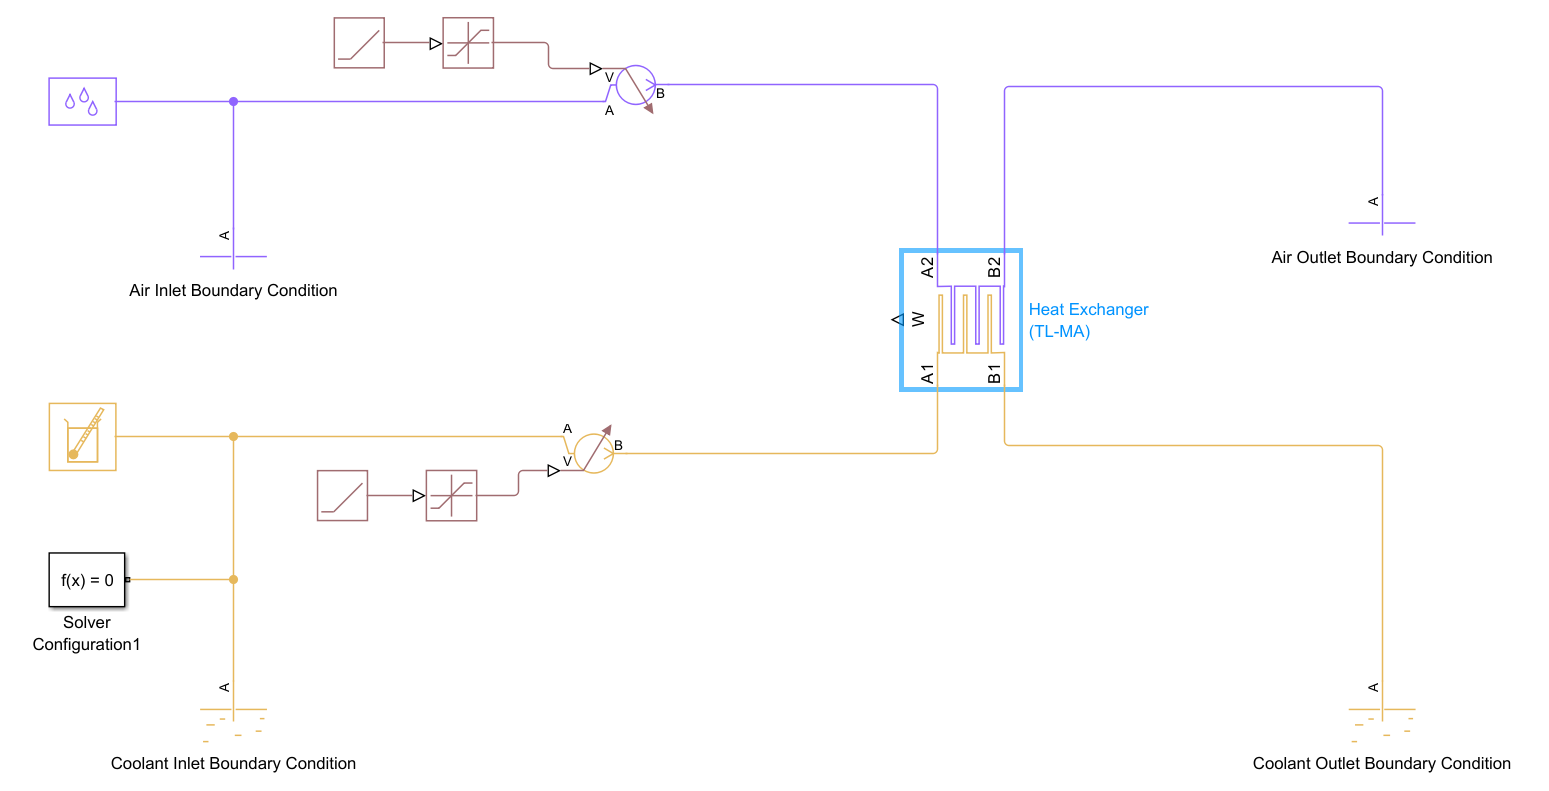

The model is setup with the above parameters. The Moist Air Side has the *Flow Geometry* set to Generic, in this case the model uses the Colburn equation to calculate the Nusselt number. 

**Todo:   - reference paramaters for Colburn equation, Wall Thermal resistance **

On the Thermal Liquid side the model is initialized at the assumed loop pressure and the cold plate outlet temperature. On the air side the model is initialized at ambient pressure and temperature. As in previous models we set the Cross-sectional areas of connected ports to similar values. On the Thermal Liquid side, this is the tube cross-sectional area. On the air side the flow area in the radiator. 

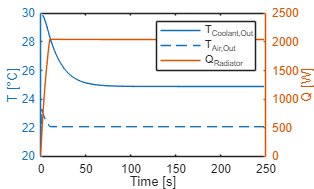

simInp = Simulink.SimulationInput("example_Radiator");
simInp = simInp.setModelParameter("StopTime","250");

simOut = sim(simInp);

TCoolantRadiatorOut = simOut.simlog.Heat_Exchanger_TL_MA.B1.T.series.values('degC');
TAirRadiatorOut     = simOut.simlog.Heat_Exchanger_TL_MA.B2.T.series.values('degC');
QRadiator           = simOut.simlog.Heat_Exchanger_TL_MA.Q2.series.values('W');
figure
yyaxis left
plot(simOut.tout,[TCoolantRadiatorOut,TAirRadiatorOut])
ylabel('T [°C]')
yyaxis right
plot(simOut.tout,QRadiator)
ylabel('Q [W]')
xlabel('Time [s]')
legend('T_{Coolant,Out}','T_{Air,Out}','Q_{Radiator}')

#### Determine the radiator pressure drop

Similar to the Pipe (TL) block the pressure drop for the Thermal Liquid side, when the Pressure loss model is set to Correlations for flow inside tubes is determined using a Haaland approximation to calculate the Darcy friction factor. 

**Todo:   - reference paramaters for Colburn equation, Wall Thermal resistance **

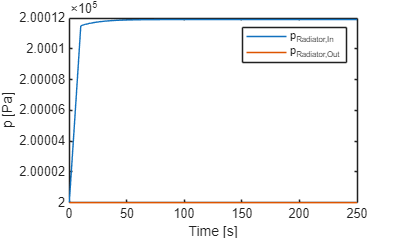

open_system("example_Radiator")

simInp = Simulink.SimulationInput("example_Radiator");
simInp = simInp.setModelParameter("StopTime","250");

simOut = sim(simInp);

pCoolantRadiatorIn  = simOut.simlog.Heat_Exchanger_TL_MA.A1.p.series.values('Pa');
pCoolantRadiatorOut = simOut.simlog.Heat_Exchanger_TL_MA.B1.p.series.values('Pa');

dpRadiator = pCoolantRadiatorIn-pCoolantRadiatorOut;

figure
plot(simOut.tout,[pCoolantRadiatorIn,pCoolantRadiatorOut])
ylabel('p [Pa]')
xlabel('Time [s]')
legend('p_{Radiator,In}','p_{Radiator,Out}')
hold off


disp(dpRadiator(end))

   11.8997



At steady state for the maximum flow rate, the current cold plate design produces a pressure drop of roughly 12 Pa, which is as expected very small compared to what is caused by the cold plate. 